## The Spectral Collocation Method for Solving Boundary Value Problems

In this livescript, you will learn how

- To solve boundary value problems using the spectral collocation method.

Consider the linear two point boundary value problem


$$\frac{d^{2}y}{dx^{2}}+2\frac{dy}{dx}-6y=0$$


with the boundary conditions $y(-1)=1$ an $y'(1)=1$.

y0 = 1;
yN = 1;

To solve this numerically using the spectral collocation method, the steps are basically the same as with finite difference methods.

Fortunately, meshing in the Spectral collocation method isn't much of an issue as the points are defined using the Gauss-Lobatto nodes.

N = 10;
xp = GLL_nodes(N);

To solve the differential equation numerically, we first need to approximate the derivative terms, which can be done using the derivative matrix.

D = DerivMatrix(xp,N);
D2 = D*D;

Now, notice how we may write the differential equation as


$$L[y]=\Big(\frac{d^{2}}{dx^{2}}+2\frac{d}{dx}-6\Big)y=0$$


This therefore shows us that we can approximate $L$ as

L = D2+2*D-6*eye(size(D));
b = zeros(N+1,1);

Now, to apply boundary conditions, the Dirichlet boundary condition at $x=-1$ may be determined in the same manner as a finite difference method. By eliminating the corresponding rows and columns from the $[L]$ matrix and moving the influence of the nodes to the $\{b\}$ vector.

L_sys = L(2:end,2:end);
b = b(2:end)-y0*L(2:end,1);

As for the Neumann boundary condition, in this case we can't just use a different differencing method near the wall, so we'll have to modify the methods discussed earlier to use a spectral method. 

Since the derivatives are given by the derivative matrix, we replace the equation at the node $x=1$ with an equation for the derivative.


$$\pmatrix{
D_{N0} & D_{N1} & \cdots & D_{NN}
}
\pmatrix{
y_{0}\cr
y_{1}\cr
\vdots\cr
y_{N}
}
=
y_{N}$$


Expanding the $y_{0}$ term out as it's the dirichlet boundary condition at $x=-1$, we have


$$\pmatrix{
D_{N1} & \cdots & D_{NN}
}
\pmatrix{
y_{1}\cr
\vdots\cr
y_{N}
}
=
y_{N}
-
D_{N0}y_{0}$$


which we may replace in $[L]$ and $\{b\}$ using

L_sys(end,:) = D(end,2:end);
b(end) = yN-D(end,1)*y0;

And so, solving gives

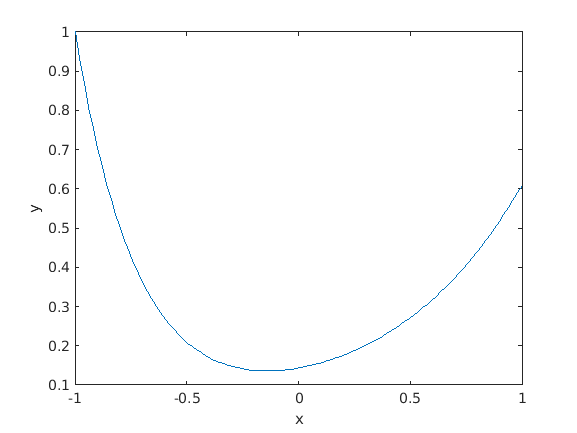

sol = L_sys\b;
y = [y0;sol];

plot(linspace(-1,1,100),LagrangePolynomial(xp,y,N,linspace(-1,1,100)));
xlabel('x')
ylabel('y')

function D=DerivMatrix(x,n)
    D=zeros(n+1,n+1);
    for i=1:n+1    
        num(i)=1.0;    
        for k=1:n+1        
            if k ~= i            
                num(i)=num(i)*(x(i)-x(k));        
            end    
        end
    end
    for j=1:n+1    
        den(j)=1.0;    
        for k=1:n+1        
            if k ~= j            
                den(j)=den(j)*(x(j)-x(k));        
            end    
        end
    end
    for i=1:n+1    
        for j=1:n+1        
            if i ~= j            
                D(i,j)=num(i)/(den(j)*(x(i)-x(j)));        
            end    
        end
    end
    for i=1:n+1    
        for k=1:n+1        
            if i~=k            
                D(i,i)=D(i,i)+1./(x(i)-x(k));        
            end    
        end
    end
end   


function yint=LagrangePolynomial(x,y,n,xint)
    yint=zeros(size(xint));
    for i=1:n+1    
        Lix=1.0;    
        for j=1:n+1        
            if j ~= i        
                Lix=Lix.*(xint-x(j))/(x(i)-x(j));        
            end    
        end    
        yint=yint+y(i).*Lix;
    end
end

function xp = GLL_nodes(N)
    
    syms x
    Lo = (1-x^2)*diff(legendreP(N,x),x);
    xp = double(vpasolve(Lo == 0));
    
end